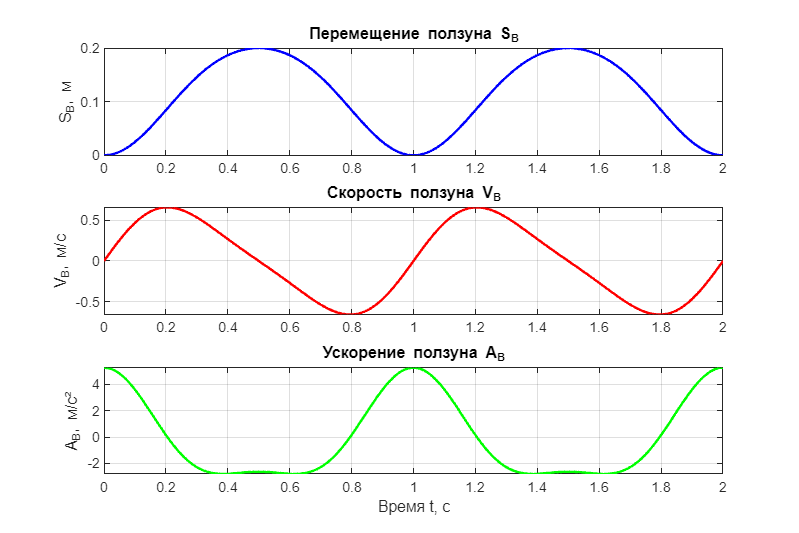

% Параметры моделирования
T = 2; % Длительность моделирования (с)
N = 1000; % Количество точек
t = linspace(0, T, N); % Создание массива времени

% Расчет кинематических параметров (пример)
% Здесь должны быть ваши реальные формулы расчета
omega = 2*pi; % Угловая скорость кривошипа
r = 0.1; % Длина кривошипа
l = 0.3; % Длина шатуна

% Расчет перемещения, скорости и ускорения ползуна
S_B = r*(1 - cos(omega*t)) + (r^2/(4*l))*(1 - cos(2*omega*t));
V_B = r*omega*(sin(omega*t) + (r/(2*l))*sin(2*omega*t));
A_B = r*omega^2*(cos(omega*t) + (r/l)*cos(2*omega*t));

% Построение графиков кинематических параметров
figure('Name', 'Кинематические характеристики ползуна', 'Position', [100, 100, 900, 600]);

subplot(3,1,1);
plot(t, S_B, 'b', 'LineWidth', 1.5);
grid on; title('Перемещение ползуна S_B');
ylabel('S_B, м');

subplot(3,1,2);
plot(t, V_B, 'r', 'LineWidth', 1.5);
grid on; title('Скорость ползуна V_B');
ylabel('V_B, м/с');

subplot(3,1,3);
plot(t, A_B, 'g', 'LineWidth', 1.5);
grid on; title('Ускорение ползуна A_B');
xlabel('Время t, с'); ylabel('A_B, м/с²');